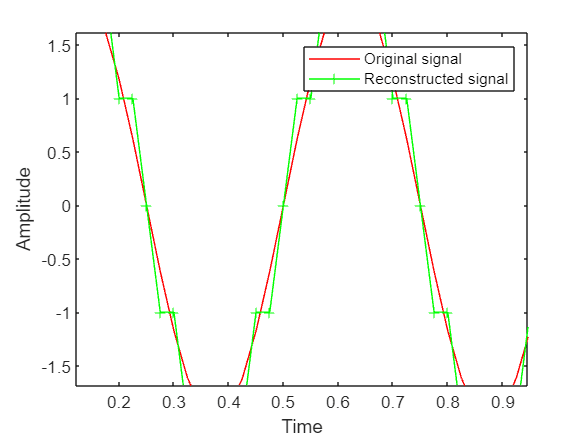

% PCM
% Sinusoidal analog signal
f=2;           % maximum frequency of the input signal
fs=20*f;    % Nyquist sampling rate
t=0:1/fs:1;   % time
a=2;      % amplitude
x=a*sin(2*pi*f*t);
% level shifting
x1=x+a; 
% Quantization
q_op=round(x1);
% decimal to binary conversion
enco=de2bi(q_op,'left-msb');
% PCM receiver
deco=bi2de(enco,'left-msb');
% Shifting the amplitude level to the original value 
xr=deco-a;
% plotting
plot(t,x,'r-',t,xr,'g+-');
xlabel('Time');
ylabel('Amplitude');
legend('Original signal','Reconstructed signal');